# Gabriel Colangelo

clear
close all
clc

## Problem 2a)


$$\underline{Find}: r_p, v_p, b,h,\delta, v_\infty, \epsilon, r, v, \gamma, H, \text{time to perilune}$$


Assume passage altitude equals altitude at periapsis (i.e. $r_p$ = 800 km)

% Magnitude of semi major axis for hyperbolic orbit
a_abs       = 7050; % [km]

% True anoamly at current time
ta0         = -90;  % [deg]

% Passage altitude (equals periapsis)
rp          = 800;  % [km]

% Moon gravitonal parameter
mu_moon     = 4902.8005821478; % [km^3/s^2]

% Velocity at periapsis
vp          = sqrt(2*mu_moon/rp + mu_moon/a_abs);
fprintf('The velocity at periapsis is %.2f km/s',vp)

The velocity at periapsis is 3.60 km/s


$$\epsilon = \frac{\mu}{2|a|} = \frac{v^2}{2} - \frac{\mu}{r} \\
v_p = \sqrt{\frac{2\mu}{r_p} + \frac{\mu}{|a|}} = 3.60\ [km/s]$$


% Calculate enegry
energy      = mu_moon/(2*a_abs);
fprintf('The orbit specific energy is %.3f km^2/s^2', energy)

The orbit specific energy is 0.348 km^2/s^2


$$\epsilon = \frac{\mu}{2|a|} = 0.35 \ [km^2/s^2]$$


% Calculate eccentricity
e           = rp/a_abs + 1;

% Calculate semi minor axis
b           = a_abs*sqrt(e^2 -1);
fprintf('Semi minor axis is %.1f km ', b)

Semi minor axis is 3452.5 km 


$$r_p = |a|(e - 1) \\
e = \frac{r_p}{|a|} + 1 \\
b = |a|\sqrt{e^2 - 1} = 3452.5 \ [km]$$


% Calculate semi-latus rectrum
p           = a_abs*(e^2 - 1);

% Calculate specific angular momentum
h           = sqrt(mu_moon*p);
fprintf('Specific angular momentum is %.2f km^2/s',h)

Specific angular momentum is 2879.16 km^2/s


$$p = |a|(e^2 - 1)\\
h = \sqrt{\mu p} = 2879 \ [km^2/s]$$


% Calculate fly-by angle
delta       = 2*asind(1/e);
fprintf('The fly by angle is %.2f deg', delta)

The fly by angle is 127.82 deg


$$cos(\theta^*_\infty) = \frac{-1}{e} = -\sin{\frac{\delta}{2}} \\
\delta = 2 \sin^{-1}{(\frac{1}{e})} = 127.8 \ [deg]$$


% Calculate excess velocity 
vinf        = sqrt(mu_moon/a_abs);
fprintf('Excess velocity is %.3f km/s', vinf)

Excess velocity is 0.834 km/s


$$v_\infty = \sqrt{\frac{2\mu}{r_\infty} + \frac{\mu}{|a|}} = \sqrt{\frac{\mu}{|a|}} = 0.83\ [km/s]$$


% Calculate current altitude
r           = p/(1 + e*cosd(ta0));
fprintf('Current altitude is %.2f km',r)

Current altitude is 1690.78 km


$$r = \frac{p}{1 + e\cos{\theta^*}} = 1690.8 \ [km]$$


% Calculate velocity magnitude
v           = sqrt(2*mu_moon/r + mu_moon/a_abs);
fprintf('The current speed is %.3f km/s', v)

The current speed is 2.549 km/s


$$v = \sqrt{\frac{2\mu}{r} + \frac{\mu}{|a|}} = 2.55\ [km/s]$$


% Flight path angle (negative due to sign of true anomaly)
gamma       = sign(ta0)*acosd(h/(r*v));
fprintf('The current flight path angle is %.2f deg',gamma)

The current flight path angle is -48.07 deg


$$\cos{\gamma} = \frac{h}{rv} \\
\gamma = -48.1 \ [deg]$$


% Calculate hyperbolic anomaly (negative due to sign of true anomaly)
H           = sign(ta0)*acosh((r/a_abs + 1)/e);
fprintf('The current hyperbolic anomaly is %.3f ', H)

The current hyperbolic anomaly is -0.472 


$$r = |a|(e\cosh{H}-1) \\
H = \cosh^{-1}{\frac{\frac{r}{|a|} + 1}{e}} = -0.47$$


% Time to perilune
dtp         = -(e*sinh(H) - H)/sqrt(mu_moon/a_abs^3);
fprintf('Time to perilune is %.2f hours',dtp/60);

Time to perilune is 10.33 hours


$$\sqrt{\frac{\mu}{|a|^3}} (t - t_p) = e\sinh{H}  - H \\
(t_p - t) = -\frac{e\sinh{H}  - H}{\sqrt{\frac{\mu}{|a|^3}}} = 10.33 \ [min]$$


## Problem 2b)

Find: True anomaly and actual radius at aim point

% True anomaly at aim point
ta_aim      = -delta/2;
fprintf('True anomaly at aim point is %.2f deg', ta_aim)

True anomaly at aim point is -63.91 deg


$$\theta^*_{b} = -\frac{\delta}{2}$$


% Radius at aim point
r_aim       =  p/(1 + e*cosd(ta_aim));
fprintf('The radius at the aim point is %.2f km',r_aim)

The radius at the aim point is 1134.96 km


$$r = \frac{p}{1 + e\cos{\theta^*}} = 1135.0 \ [km]$$


## Problem 2c) Plot Hyperbola

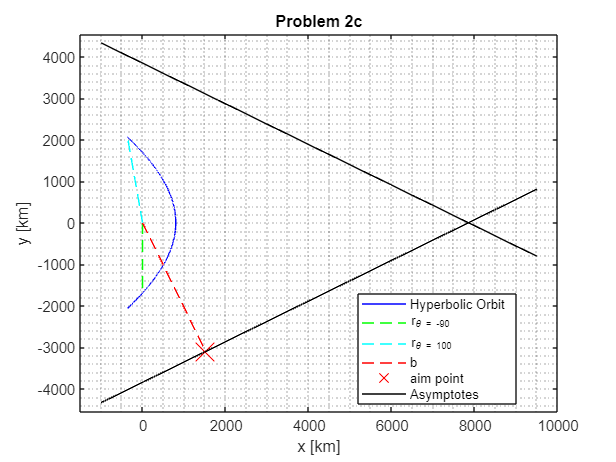

% True Anomaly Vector
ta_vec      = -100:.01:100;

% Initialize Perifocal position vector
r_P         = zeros(2,length(ta_vec)); 

for i = 1:length(ta_vec)

    % Distance to probe from moon
    r_mag     =  p/(1 + e*cosd(ta_vec(i)));

    % Position Vector in Perifocal Frame - Centered at Moon 
    r_P(:,i)  = [r_mag*cosd(ta_vec(i));r_mag*sind(ta_vec(i))]; 

    if ta_vec(i) == -90
        indn90 = i;
    elseif ta_vec(i) == 100
        ind100 = i;
    end
    
    % % Calculate Hyperbolic anomaly
    % H         = 2*atanh(tand(ta_vec(i)/2)/sqrt((1+e)/(e - 1)));
    % 
    % % Position Vector in Perifocal Frame 
    % r_P2(:,i)  = [-a_abs*cosh(H) + (a_abs*e);b*sinh(H)]; 

end

% Calculate asymptote
ta_inf      = acosd(-1/e);

% Slope of line
slope       = tand(ta_inf - delta);

% Create asymptote
asym        = slope*((-1000:10:9500) - a_abs*e);

figure
plot(r_P(1,:),r_P(2,:),'-b')
%plot(r_P(1,:),r_P(2,:),'-b',r_P2(1,:),r_P2(2,:),'--k')
hold on
plot([0, r_P(1,indn90)], [0, r_P(2,indn90)],'Color','green','Linestyle','--')
plot([0, r_P(1,ind100)], [0, r_P(2,ind100)],'Color','cyan','Linestyle','--')
plot([0, b*cosd(ta_aim)], [0, b*sind(ta_aim)],'Color','red','Linestyle','--')
plot(b*cosd(ta_aim),b*sind(ta_aim),'rx','MarkerSize',18)
plot((-1000:10:9500), -asym,'-k')
plot((-1000:10:9500), asym,'-k')
title('Problem 2c')
axis equal
grid minor
hold on
xlabel('x [km]')
ylabel('y [km]')
legend('Hyperbolic Orbit','r_{\theta = -90}','r_{\theta = 100}','b','aim point','Asymptotes',...
       'Location', 'best')
hold off
xlim([-1500 10000])

% Calculate position for true anomaly 100 degrees
r_100       = p/(1 + e*cosd(100));
fprintf('The radius for a true anomaly of 100 degrees is %.1f km', r_100)

The radius for a true anomaly of 100 degrees is 2096.1 km


$$r = \frac{p}{1 + e\cos{\theta^*}} = 2096.1 \ [km]$$


% Calculate velocity for true anomaly 100 degrees
v_100       = sqrt(2*mu_moon/r_100 + mu_moon/a_abs);
fprintf('The speed for a true anomaly of 100 degrees is %.3f km/s', v_100)

The speed for a true anomaly of 100 degrees is 2.318 km/s


$$v = \sqrt{\frac{2\mu}{r} + \frac{\mu}{|a|}} = 2.32\ [km/s]$$


% Calculate flight path angle - positive due to ascending
gamma_100   = acosd(h/(r_100*v_100));
fprintf('The flight path angle for a true anomaly of 100 degrees is %.2f deg', gamma_100)

The flight path angle for a true anomaly of 100 degrees is 53.66 deg


$$\cos{\gamma} = \frac{h}{rv} \\
\gamma = 53.66\ [deg]$$
